addpath(genpath('/datascience/projects/statisticallyfit/github/MATLAB/MatlabTutorial/AMTH250_NumericalMatlab/Numerical Analysis/Root Finding'))

Question 1 a)

n = 4, nMax = 100, solution = 1.8342432


ans =    1.834243184314032


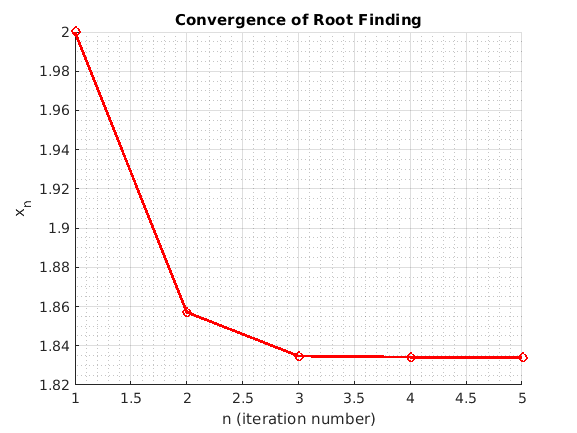

f = @(x) x.^3 - 5*x+3;
fd = @(x) 3*x.^2 - 5;
newtonP(f, fd, 2, 6)

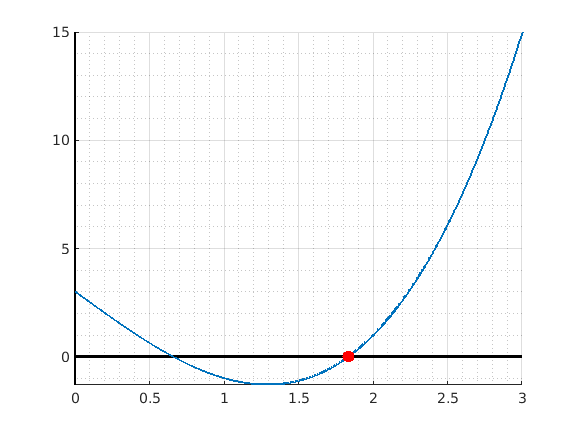

plotRoot(f, 0, 3)

Question 1 b)

n = 6, nMax = 100, solution = 1.150000


ans =    1.150000000000000


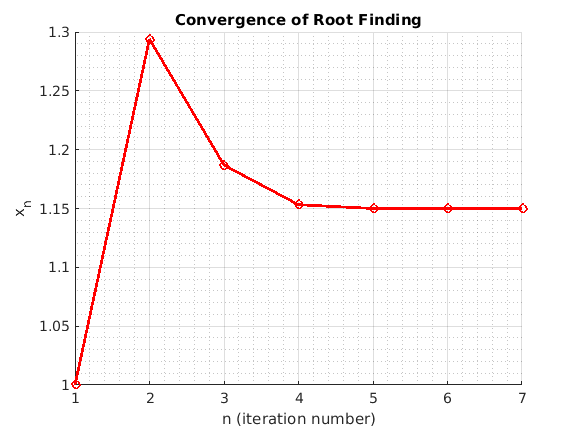

f = @(x) x.^5 + 0.85*x.^4 + 0.7*x.^3 -3.45*x.^2 - 1.1*x + 1.265;
fd = @(x) 5*x.^4 + 4*0.85*x.^3 + 2.1*x.^2 -2*3.45*x -1.1;
newtonP(f, fd, 1, 6)

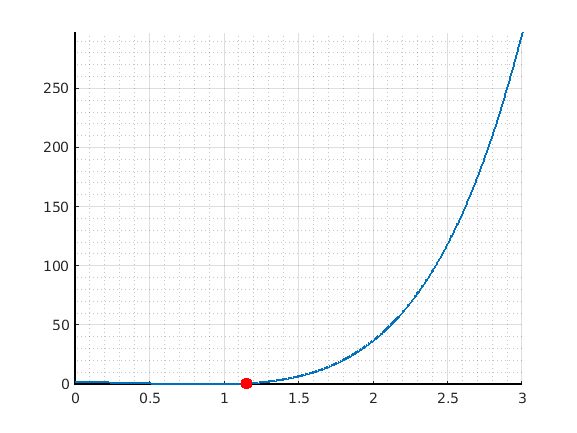

plotRoot(f, 0,3)

Question 1c)

n = 4, nMax = 100, solution = 0.904557


ans =    0.904556894302381


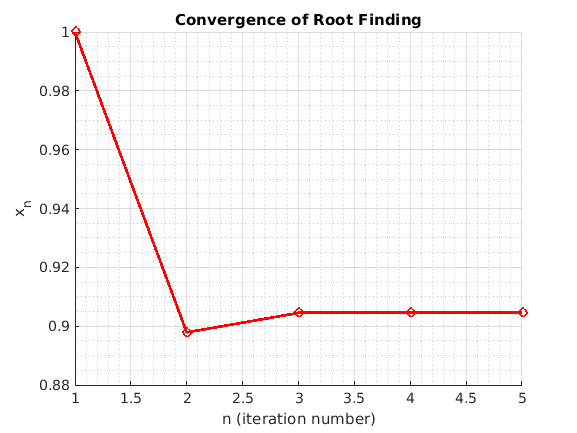

f = @(x) sin(x) - cot(x);
fd = @(x) cos(x) + csc(x)^2;
newtonP(f, fd, 1, 6)

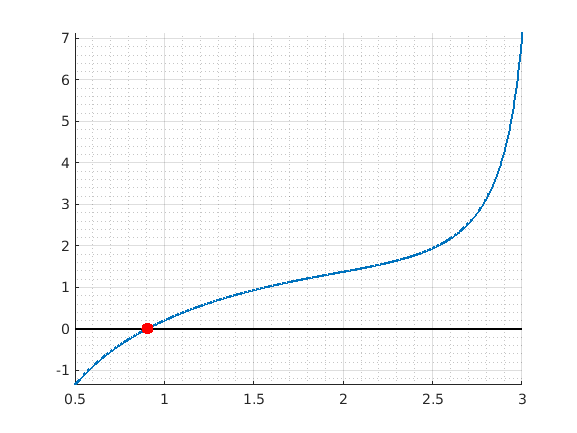

plotRoot(f, 0.5, 3)

Question 1.d)

n = 9, nMax = 100, solution = 0.652919


ans =    0.652918524495139


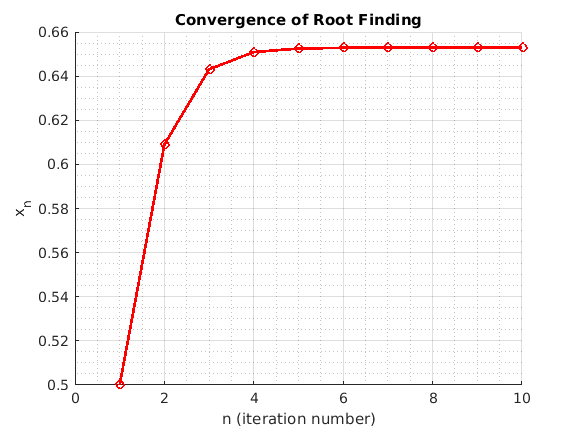

f = @(x) exp(-x.^2) - x;
fd = @(x) -2*exp(-x.^2)-1;
newtonP(f, fd, 0.5, 6)

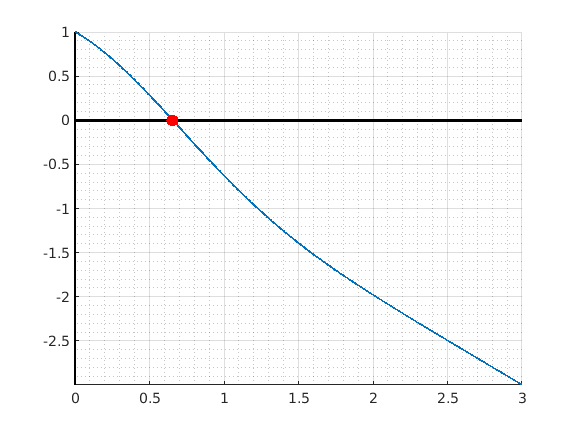

plotRoot(f, 0, 3)

Question 2

n = 4, nMax = 100, solution = 1.557146


ans =    1.557145598997611


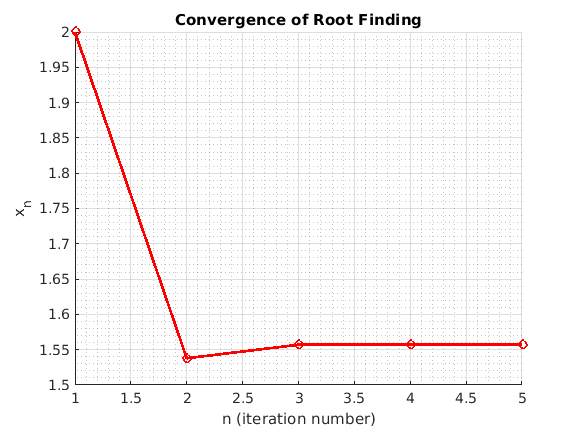

f = @(x) x + log(x) - 2;
fd = @(x) 1 + 1./x;
%newton iteration formula is: 
% xn+1 = xn - (xn + ln(xn)-2)/ (1+1/xn)
newtonP(f, fd, 2, 6)

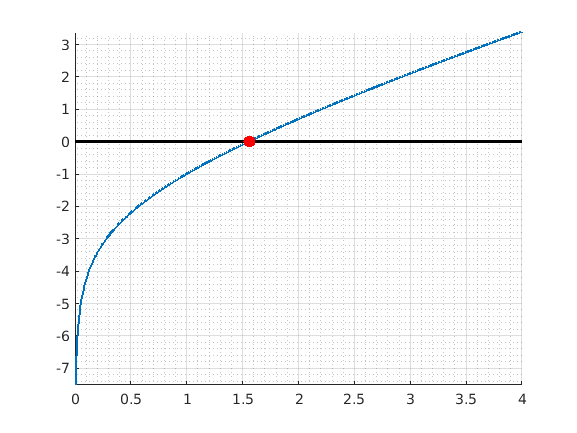

plotRoot(f, 0, 4)

Question 3: 

Approximating first when f'(2) = 0 at root =2

n = 19, nMax = 100, solution = 2.000000


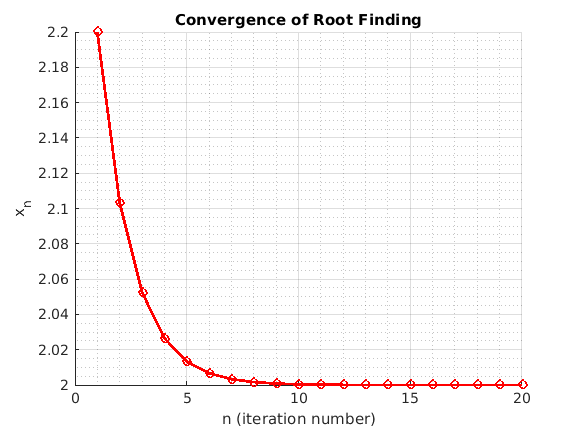

f = @(x) exp(x-2) - x+1;
df = @(x) exp(x-2) - 1;
[s, x] = newtonP(f, df, 2.2, 6); % outputs root = 2 to 6 decimals

s

s =    2.000000408036708


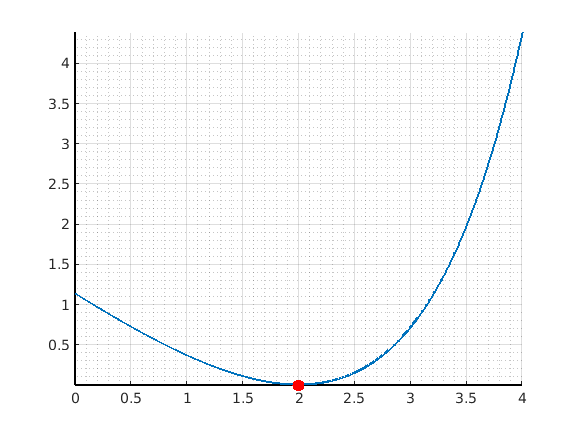

plotRoot(f, 0, 4)

log error slopes = 
   1.023768345823613
   1.012353020887929
   1.006300867817348
   1.003182485874729
   1.001599380996008
   1.000801740932229
   1.000401385038215
   1.000200821961533
   1.000100441080070
   1.000050225765851
   1.000025144242995
   1.000012554319425
   1.000006436604325
   1.000002845363884
   0.999998190343175
   0.999977187315664
   1.000065645505303
   1.000076116568466



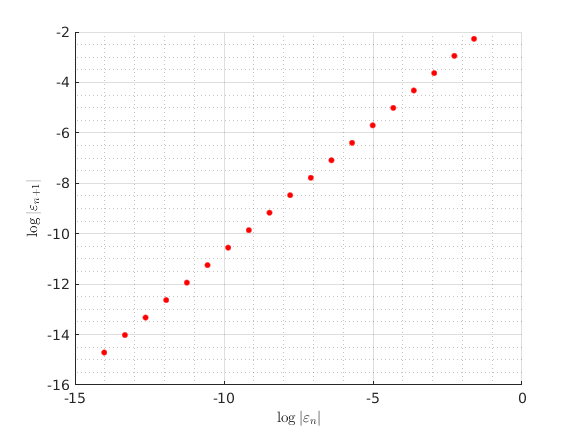

plotLogErrorWithSolution(x, 2) % slope = 1 so we have 

% % linear convergence
% with this newton method when f'(root) = 0, consistent with
% the equation |e_n+1| = A|e_n| for some const A. 

% NOTE: for n = 0,1,2, we get the first two error log slopes
% of 1.0238 and 1.01236

n = 4, nMax = 100, solution = 2.000000


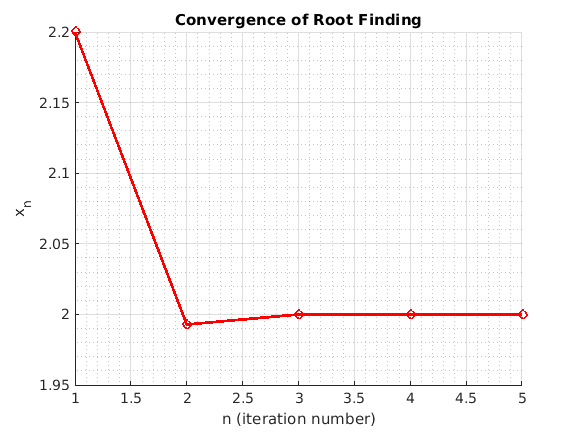

% now using modified version with h(x) = f(x) / f'(x)
% and showing quadratic convergence has come back. 
ddf = @(x) exp(x-2);
[s, x] = newtonHP(f, df, ddf, 2.2, 6);

s

s =    1.999999999998951


log error slopes = 
   2.020776376086913
   2.359975411177493
                   0



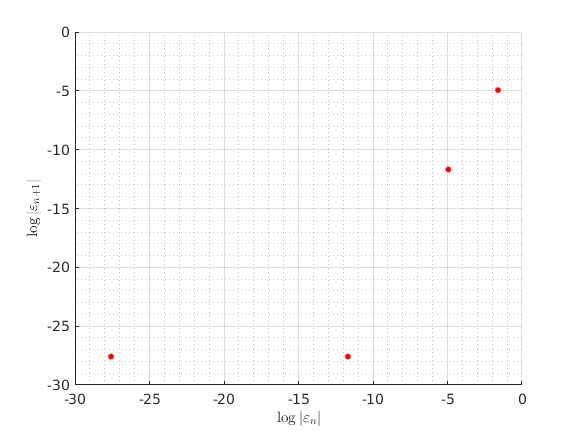

plotLogErrorWithSolution(x, 2) % now slopes = 2 so quadratic

% %conv is back. because we now have form |e_n+1| = A|e_n|^2

Question 4a)

n = 6, nMax = 20, solution = 1.834243


ans =    1.834243184314066


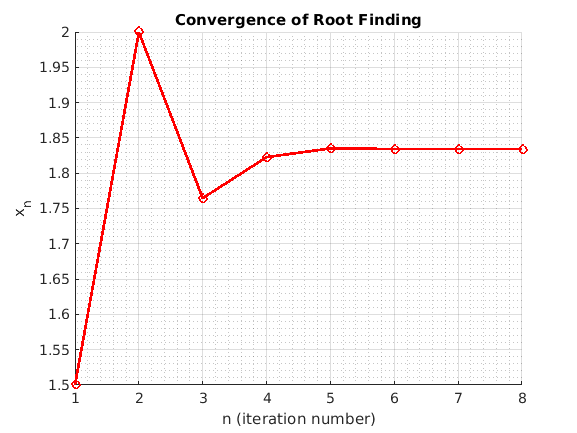

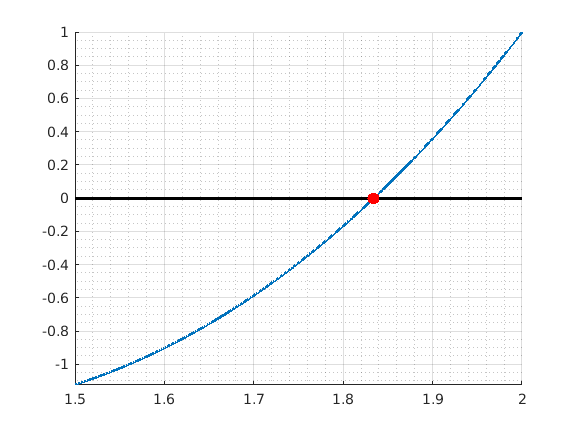

f = @(x) x.^3 - 5*x + 3;
secantP(f, 1.5, 2, 6)

question 4b)

n = 5, nMax = 20, solution = 0.507417


ans =    0.507417151746071


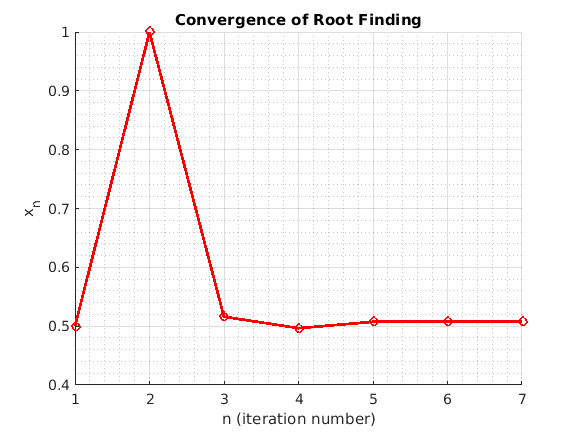

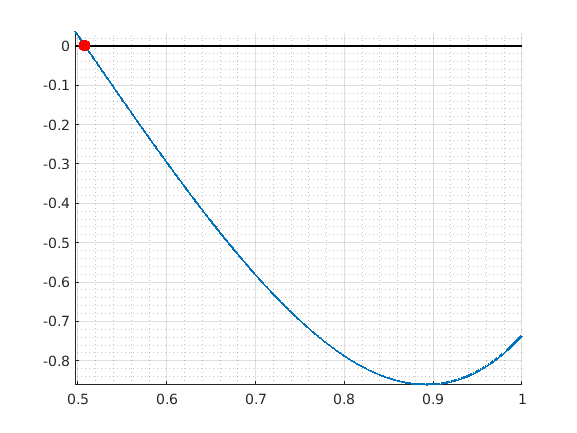

f = @(x) x.^5 + 0.85 * x.^4 + 0.7*x.^3 - 3.45*x.^2 - 1.1*x + 1.265;
secantP(f, 0.5, 1, 6)

question 4c)

n = 4, nMax = 19, solution = 0.652919


ans =    0.652918640419205


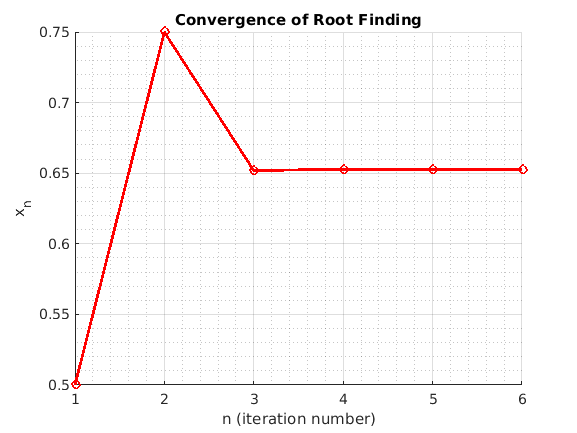

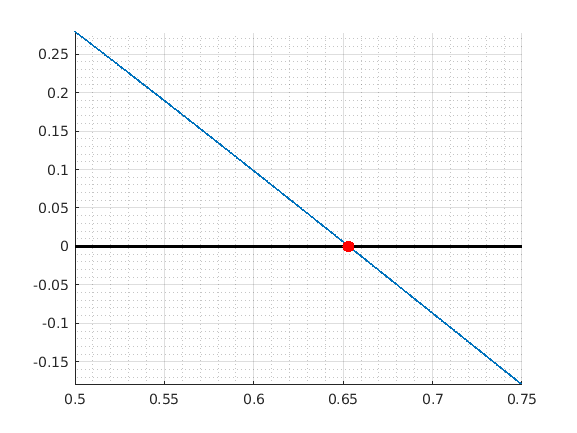

f = @(x) exp(-x.^2) - x;
secantP(f, 0.5, 0.75, 6)